I think microglia data most likely follow a log growth curve. I want to model my populations with this in mind and compare kernels.

I also want to think about M1 and M2 together as predator-prey

Questions

- What does the optimizer options in fitgrp() do? Note this is different than the hyperparameter optimization

## Data

clear; clc; close all; 
%samples
tpoints_M1 = [0,0,1,1,2,2,3,3,3,3,3,5,7,7,7,7,14,14,14]'; %time points where experimental data is observed
datapointsM1 = [0,10,5,50,120,125,375,62,102,100,60,325,600,55,900,225,750,400,1300]'; %M1 experimental data

tpoints_M2 = [0,0, 1, 1,1, 2, 2, 3,3,3,3,3, 5, 7, 7, 7, 7, 14,14,14]'; %time points where experimental data is observed
datapointsM2 = [0,10,170,15,50, 90,269,300,15,57,100,160, 800, 600,6,400,270,200,110,100]'; %M2 experimental data


%for testing
xp = linspace(0, 14, 300)'; 

%% Pre-processing
% normalize and standardize so I can use mean 1 (try with and try without)

% sqrt transform to ensure positive


% log transform to ensure positive


## **Comparing kernels **

#### **Without Bayesian optimizer**

More info about kernels: [https://www.mathworks.com/help/stats/kernel-covariance-function-options.html](https://www.mathworks.com/help/stats/kernel-covariance-function-options.html) 

Not setting any inital values for kernel parameters

Some questions:

- ***what should my basis be set to?**** Constant, linear (default is constant)*

- Using FitMethod = exact (default)* (Exact Gaussian process regression. This value is the default if n ≤ 2000, where n is the number of observations.)*

- Always using predict = exact *(Exact Gaussian process regression method. This value is the default if n ≤ 10,000.)*

- **What should standardize be ***default set to false*

- predict vs resubpredict

- What should be true x be

%Squared exponental (hyperparams: lengthsale (l))
gprMdl_SE_M1 = fitrgp(tpoints_M1,datapointsM1);
[ypred_SE_M1,~] = predict(gprMdl_SE_M1,xp);


%Exponential (aka Matern 1/2)
gprMdl_exp_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','exponential');
[ypred_exp_M1,~] = predict(gprMdl_exp_M1,xp);


%Matern 3/2 [v=3/2] (hyperparams: v, l)
gprMdl_M32_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','matern32');
[ypred_M32_M1,~] = predict(gprMdl_M32_M1,xp);

%Matern 5/2 [v=5/2] (hyperparams: v, l)
gprMdl_M52_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','matern52');
[ypred_M52_M1,~] = predict(gprMdl_M52_M1,xp);

%Rational Quadratic (hyperparams: alpha, l)
gprMdl_RQ_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','rationalquadratic');
[ypred_RQ_M1,~] = predict(gprMdl_RQ_M1,xp);

    %% ARD = automatic relevance determination
%ARD squared exponential
gprMdl_ardSE_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','ardsquaredexponential');
[ypred_ardSE_M1,~] = predict(gprMdl_ardSE_M1,xp);

%ARD exponential
gprMdl_ardExp_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','ardexponential');
[ypred_ardExp_M1,~] = predict(gprMdl_ardExp_M1,xp);

%ARD Matern 3/2
gprMdl_ardM32_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','ardmatern32');
[ypred_ardM32_M1,~] = predict(gprMdl_ardM32_M1,xp);


%ARD Matern 5/2
gprMdl_ardM52_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','ardmatern52');
[ypred_ardM52_M1,~] = predict(gprMdl_ardM52_M1,xp);

%ARD rational quadratic
gprMdl_ardRQ_M1 = fitrgp(tpoints_M1,datapointsM1, 'KernelFunction','ardrationalquadratic');
[ypred_ardRQ_M1,std] = predict(gprMdl_ardRQ_M1,xp);

%%To explore later %%
%non-stationary kernels
%combinging kernels through sums or products

#### Plot

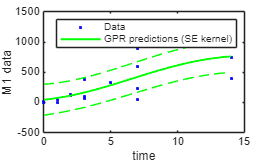


%Squared exponental 
plot(tpoints_M1,datapointsM1,'b.');
hold on;
plot(xp,ypred_SE_M1,'g','LineWidth',1.5);
plot(xp, ypred_SE_M1+std, 'g--');
plot(xp, ypred_SE_M1-std, 'g--');
xlabel('time');
ylabel('M1 data');
legend('Data','GPR predictions (SE kernel)');
hold off

#### Compute marginal log liklihood

%I want to create a table where I track what was used to generate the
%model, and then put the calulated log liklihood


% I want to create a data set where I say which kernel was used, and then I
% calculate the following metrics (logliklihood, RMSE, and R^2) for each.
%so the columns will be: kernel (string), LogLikelihood (double), RMSE
%(double), and R2 (double)

%additionally, i'd ideally like to set up the below code in some sort of
%loop or other efficient codeblock to be able to calculate or find the
%below metrics for each gprmdl that I made above, and then put the relevant
%information in the table. 



gprMdl_SE_M1.LogLikelihood

ans = -134.2327

RMSE = sqrt(mean(residuals.^2));
SSR = sum((yPredict - mean(yActual)).^2);  % Regression sum of squares
SST = sum((yActual - mean(yActual)).^2);   % Total sum of squares
R2 = SSR / SST;

#### **With Hyperparameter optimization**

Parameters to optimize, specified as one of the following:

- `'none'` — Do not optimize.

- `'auto'` — Use `{'Sigma','Standardize'}`.

- `'all'` — Optimize all eligible parameters, equivalent to `{'BasisFunction','KernelFunction','KernelScale','Sigma','Standardize'}`.

- String array or cell array of eligible parameter names.

- Vector of `optimizableVariable` objects, typically the output of [`hyperparameters`](https://www.mathworks.com/help/stats/hyperparameters.html).

The optimization attempts to minimize the cross-validation loss (error) for `fitrgp` by varying the parameters. To control the cross-validation type and other aspects of the optimization, use the [`HyperparameterOptimizationOptions`](https://www.mathworks.com/help/stats/fitrgp.html#butnn96_sep_shared-HyperparameterOptimizationOptions) name-value argument. When you use `HyperparameterOptimizationOptions`, you can use the (compact) model size instead of the cross-validation loss as the optimization objective by setting the `ConstraintType` and `ConstraintBounds` options.

Note: The values of `OptimizeHyperparameters` override any values you specify using other name-value arguments. For example, setting `OptimizeHyperparameters` to `"auto"` causes `fitrgp` to optimize hyperparameters corresponding to the `"auto"` option and to ignore any specified values for the hyperparameters.

COME BACK TO : Aggregate optimization results for multiple optimization problems, returned as an [`AggregateBayesianOptimization`](https://www.mathworks.com/help/stats/classreg.learning.paramoptim.aggregatebayesianoptimization.html) object. To return `AggregateOptimizationResults`, you must specify [`OptimizeHyperparameters`](https://www.mathworks.com/help/stats/fitrgp.html#butnn96-OptimizeHyperparameters) and [`HyperparameterOptimizationOptions`](https://www.mathworks.com/help/stats/fitrgp.html#butnn96_sep_shared-HyperparameterOptimizationOptions). You must also specify the `ConstraintType` and `ConstraintBounds` options of `HyperparameterOptimizationOptions`. For an example that shows how to produce this output, see [Hyperparameter Optimization with Multiple Constraint Bounds](https://www.mathworks.com/help/stats/classreg.learning.paramoptim.aggregatebayesianoptimization.html#mw_18fb71bf-a209-43e6-8055-f198157c9fe3).

#### Compute marginal log liklihood

#### For later: cross validation

For later: optimizing with minfunc